As a student of Cal Poly University, I, David Hefter, pledge that I have not knowingly given nor received any inappropriate assistance regarding Exercise 4 in accordance with the syllabus.

# **Exercise 4**

## **4.3 Assignment**

1. Fill out all values from tables

T_amb           = 25;               % Ambient temperature, °C

% GIVEN VALUES
V_dc            = 18;               % Nominal voltage, V
omega_noload    = 11800*2*pi/60;    % No-load speed, rad/s
R               = 0.68;             % Armature resistance, Ω
L               = 0.078e-3;         % Armature inductance, H
J               = 9.82e-7;          % Rotor inertia, kg*m^2
b               = 3.14e-7;          % Visous damping coefficient, N*m*s/rad
R_wh            = 4.57;             % Thermal resistance (winding to housing), W/K
R_ha            = 13.6;             % Thermal resistance (housing to ambient), W/K
tau_w           = 22;               % Thermal time-constant (winding), s
tau_h           = 646;              % Thermal time-constant (housing), s
T_all           = 125;              % Maximum acceptable winding temperature, °C

% CALCULATED VALUES
Km = omega_noload/V_dc;             % Motor constant, rad/s*V
Kv = max(roots([Km -1 Km*b*R]));    % Back-emf constant, V/s*rad
Kt = Kv;                            % Torque constant, N*m/A
i_stall = V_dc/R;                   % Stall current, A
T_stall = Kt * i_stall;             % Stall torque, N*m
i_noload = (V_dc-Kv*omega_noload)/R;% No-load current, A
dNdM = omega_noload/T_stall;        % Speed-torque gradient, rad/s*N*m

% Torque and angular velocity which provide max power
T_max = T_stall/2;
omega_max = omega_noload/2;
P_max = T_max*omega_max;            % Maximum power, W
% Efficiency at max power
eta_max = P_max/(V_dc*T_max/Kt);

% Torque and angular velocity and power at max efficiency
omega_eff=(-sqrt(b*R*Kt/Km+b^2*R^2)+Kt/Km+b*R)/(Kt/Km^2+b*R/Km)*V_dc;
T_eff = T_stall-omega_eff/dNdM;
P_eff = omega_eff*T_eff;
eta_eff = P_eff/(V_dc*(i_noload+T_eff/Kt)); % Maximum efficiency

inom = sqrt((T_all-T_amb)/(R*(R_wh+R_ha))); % Rated current, A
T_nom = inom*Kt;                            % Rated torque, N*m
P_nom = T_nom*(omega_noload-T_nom*dNdM);    % Rated power, W
C_w = tau_w/R_wh;                           % Thermal capacitance (winding), J/K
C_h = tau_h/R_ha;                           % Thermal capacitance (housing), J/K

2. Generate data to plot a motor curve, including speed, power, and efficiency each as a function of torque

T_load = linspace(0, T_stall, 1000);                                        % Torque values
P_out = omega_noload * T_load - (omega_noload / T_stall)*T_load.^2;         % Power values
omega_out = omega_noload - dNdM * T_load;                                   % Angular velocity values
num = (T_load*omega_noload) - ((omega_noload/T_stall)*T_load.^2);
denom = T_load.*(1-(b*omega_noload/T_stall)) + b*omega_noload;
eta_out = (Kt/V_dc) * num./denom;                                           % Efficiency values

3. Draw a linear graph and normal tree representing the electromechanical portion of the motor, and use them to set up a system of differential equations to describe the electromechanical system dynamics

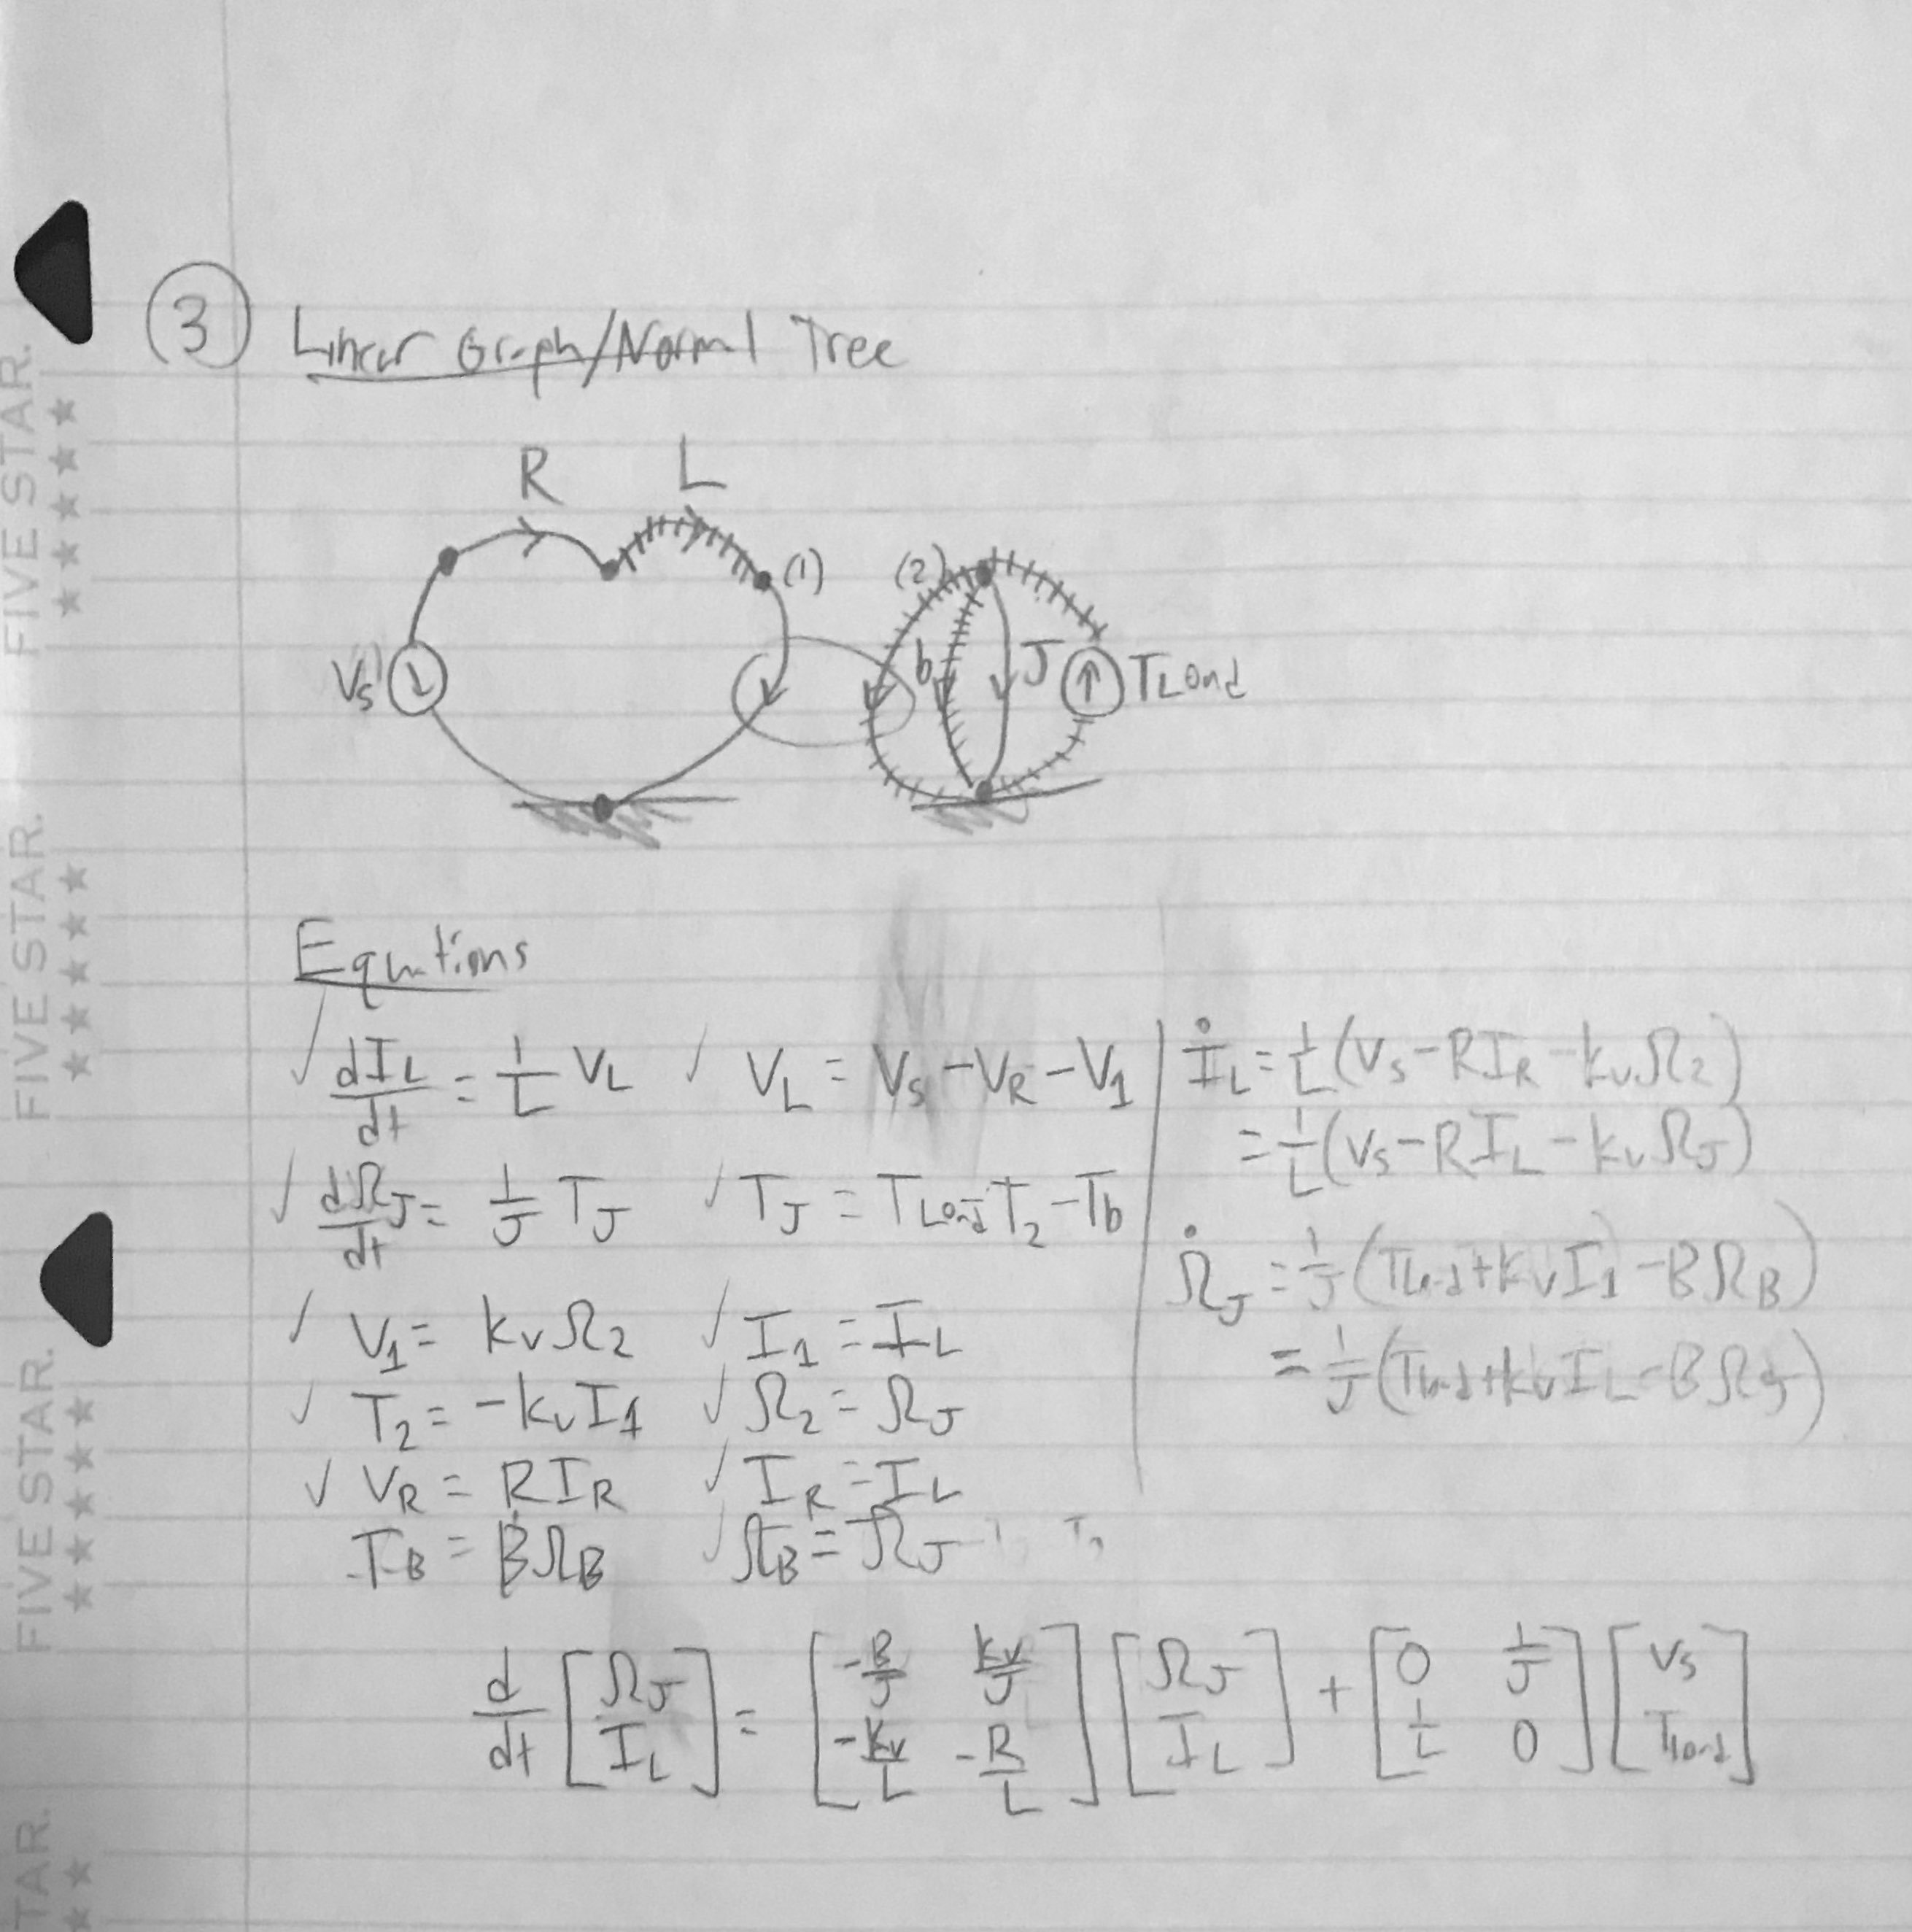

4. Draw a linear graph and normal tree representing the thermal portion of the motor, and use them to set up a system of differential equations to describe the thermal system dynamics

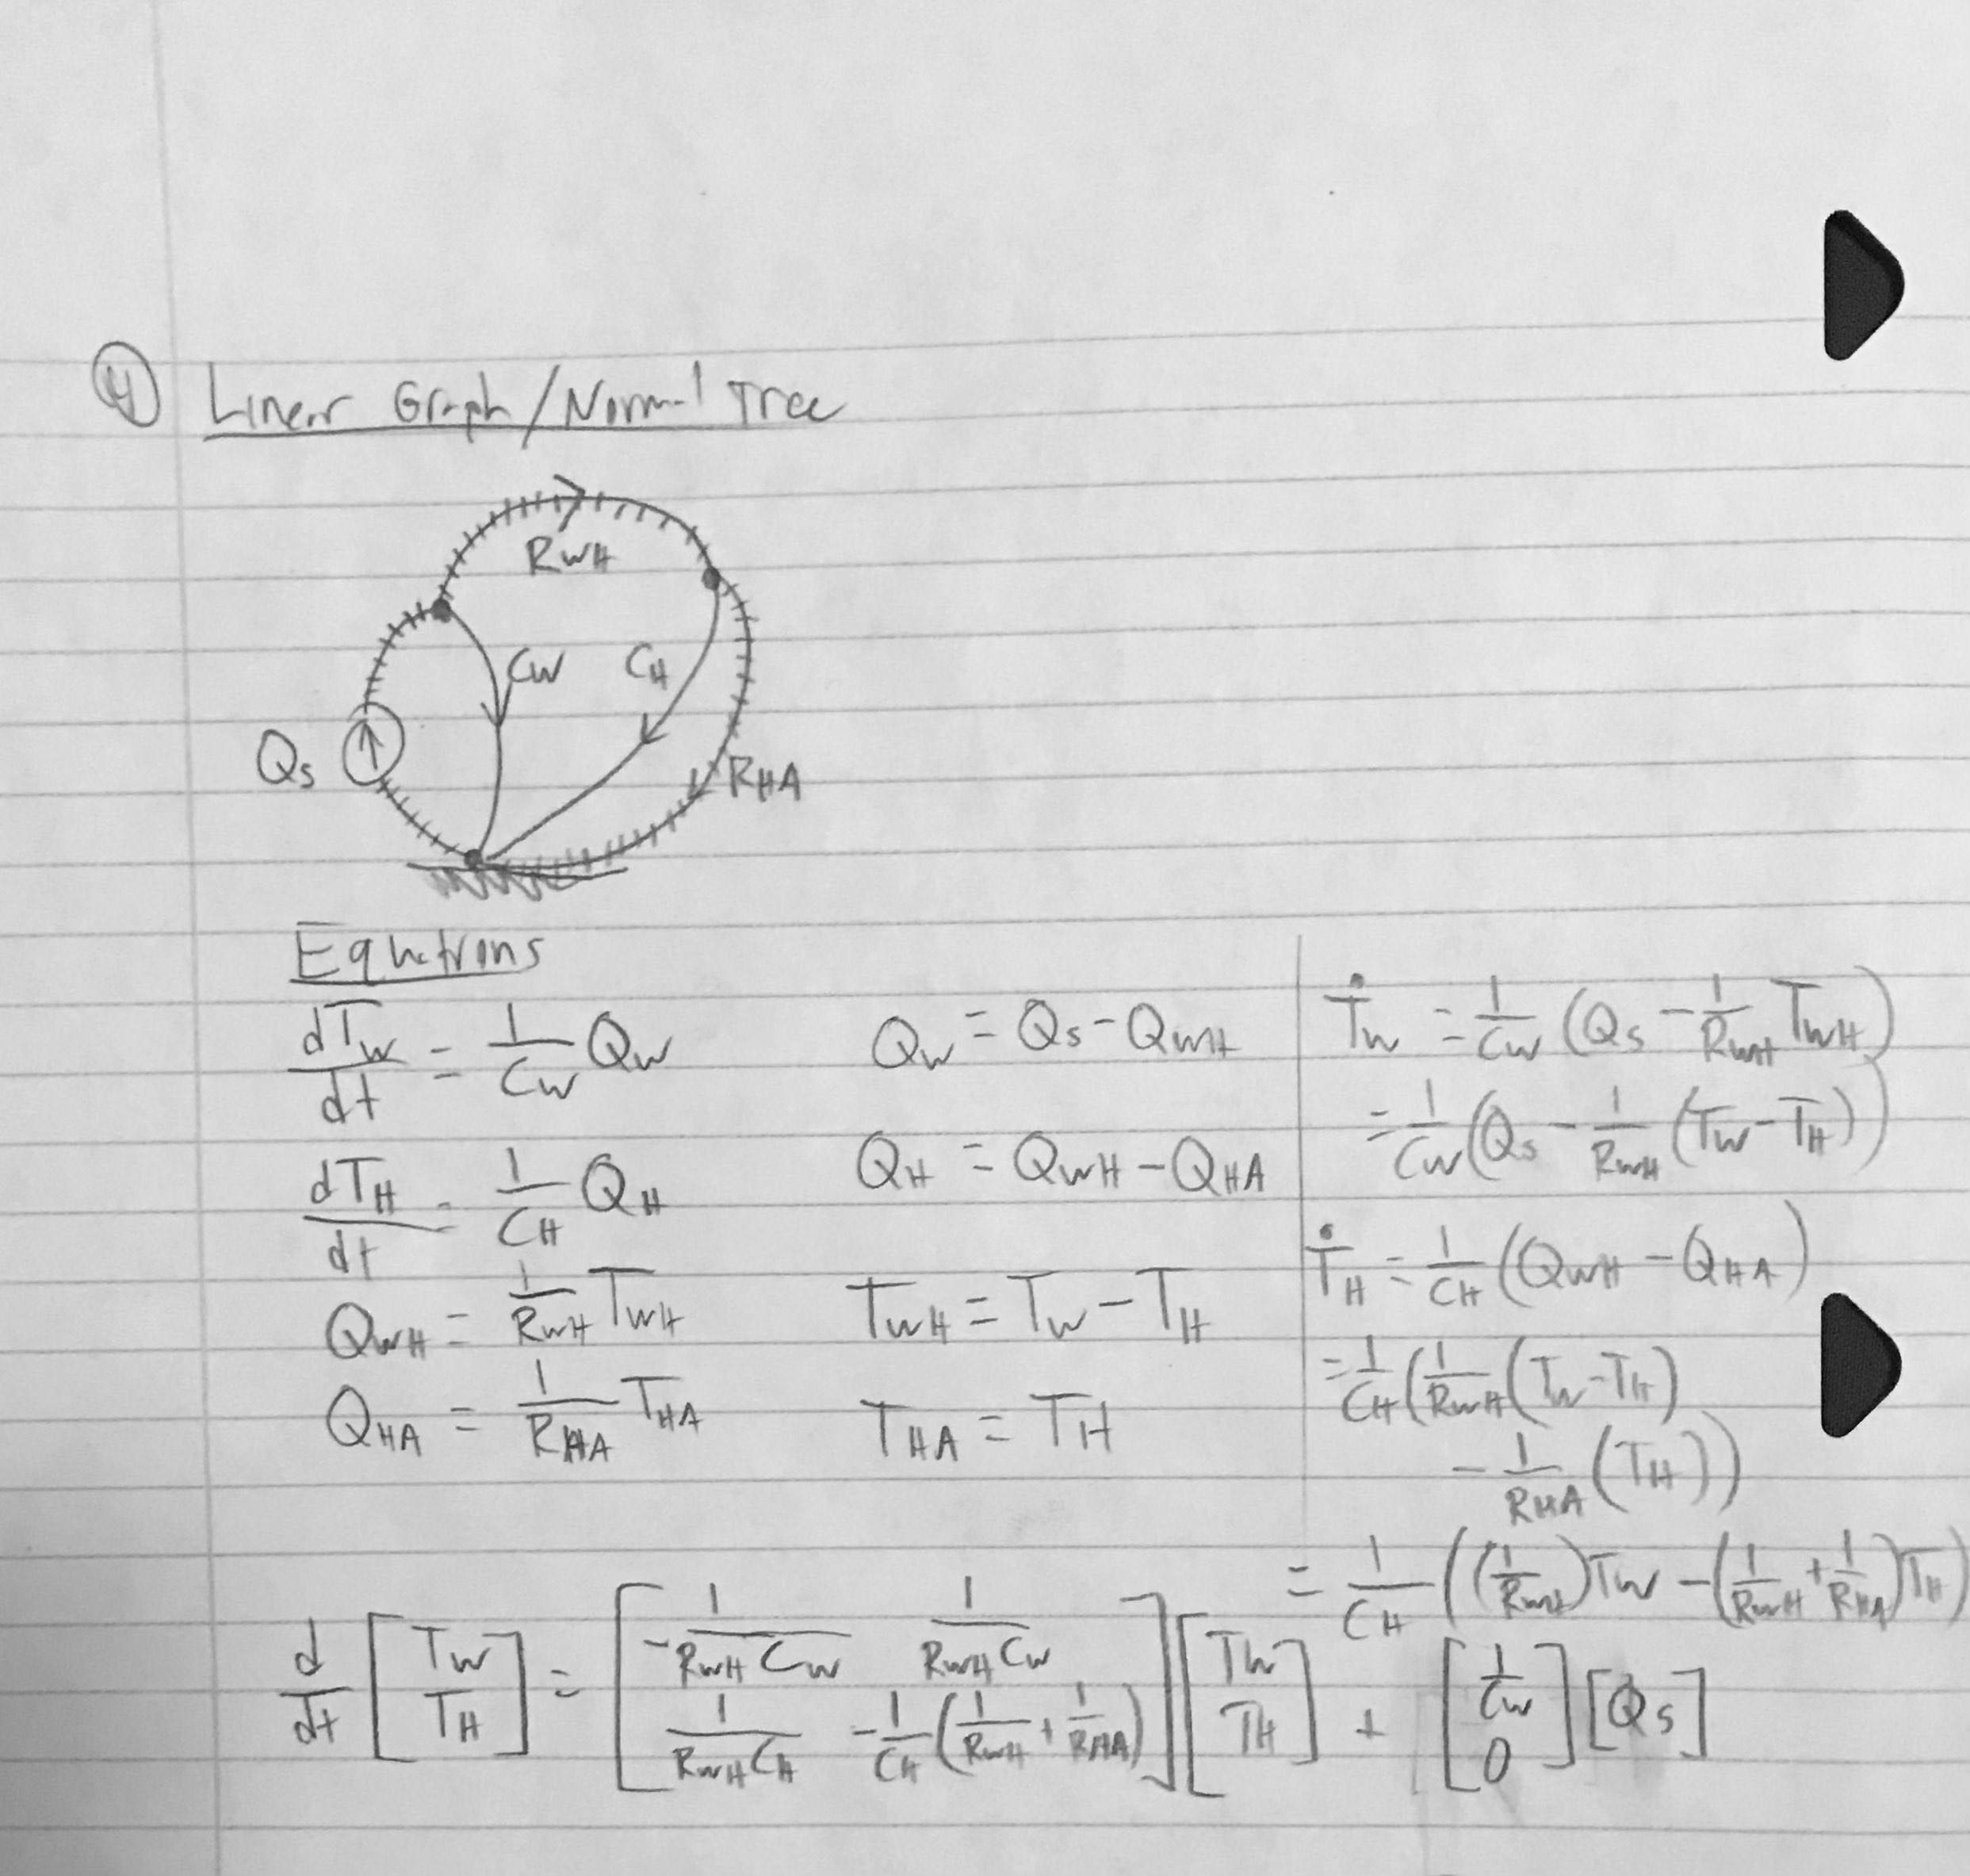

5. Create a Simulink model with two subsystems, the electromechanical subsystem and the thermal subsystem.

6. Run your simulation until both systems reach steady state for a) no load, b) nominal load, and c) stalling load

% Run no-load model
T = 0;
no_load_out = sim('lab4model');

% Run nominal-load model
T = 1;
nominal_out = sim('lab4model');

% Run stall-load model
T = 2;
stall_out = sim('lab4model');

## 4.4 Discussion and Deliverables

### 4.4.1 Tabular Data

tab = table([T_amb; V_dc; omega_noload; R; L; J; b; R_wh; ...
    R_ha; tau_w; tau_h; T_all; Km; Kv; Kt; i_stall; T_stall; i_noload; dNdM; P_max; ...
    eta_eff; inom; T_nom; P_nom; C_w; C_h],'RowNames',{'Ambient temperature, °C'; 'Nominal voltage, V'; 'No-load speed, rad/s'; ...
    'Armature resistance, Ω'; 'Armature inductance, H'; 'Rotor inertia, kg*m^2'; ...
    'Visous damping coefficient, N*m*s/rad'; 'Thermal resistance (winding to housing), W/K'; ...
    'Thermal resistance (housing to ambient), W/K'; 'Thermal time-constant (winding), s'; ...
    'Thermal time-constant (housing), s'; 'Maximum acceptable winding temperature, °C'; ...
    'Motor constant, rad/s*V'; 'Back-emf constant, V/s*rad'; 'Torque constant, N*m/A'; ...
    'Stall current, A'; 'Stall torque, N*m'; 'No-load current, A'; ...
    'Speed-torque gradient, rad/s*N*m'; 'Maximum power, W'; 'Maximum efficiency'; ...
    'Rated current, A'; 'Rated torque, N*m'; 'Rated power, W'; 'Thermal capacitance (winding), J/K'; ...
    'Thermal capacitance (housing), J/K'})

tab = 26×1 table
                                                      Var1  
                                                    ________

    Ambient temperature, °C                               25
    Nominal voltage, V                                    18
    No-load speed, rad/s                              1235.7
    Armature resistance, Ω                              0.68
    Armature inductance, H                           7.8e-05
    Rotor inertia, kg*m^2                           9.82e-07
    Visous damping coefficient, N*m*s/rad           3.14e-07
    Thermal resistance (winding to housing), W/K        4.57
    Thermal resistance (housing to ambient), W/K        13.6
    Thermal time-constant (winding), s                    22
    Thermal time-constant (housing), s

### 4.4.2 Block Diagram

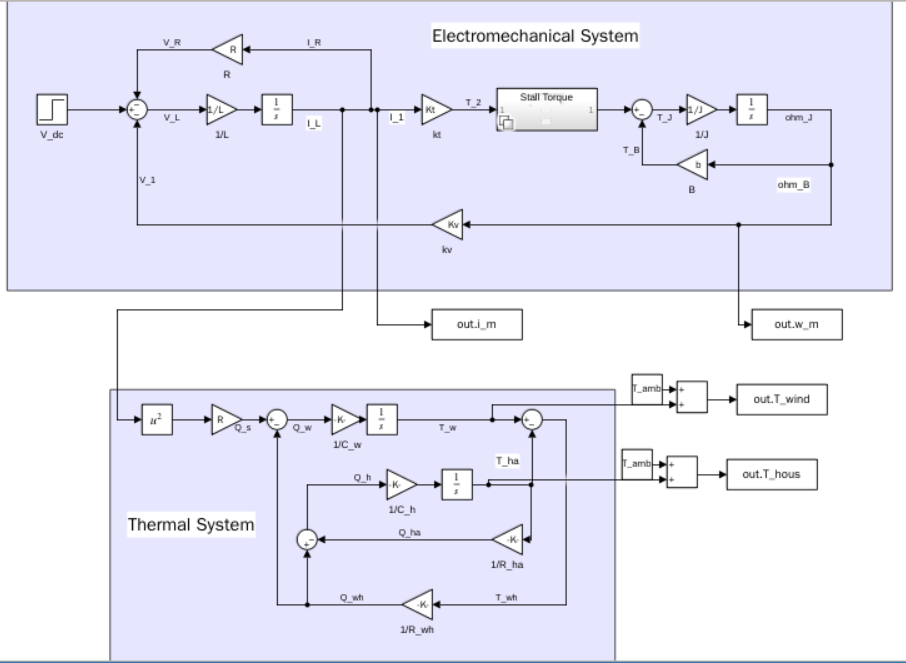

### 4.4.3 Plots

1. Plot the motor curve data showing th speed, power, and efficiency each as a function of torque. On the figure, clearly indicate the stall torque, no-load speed, maximum efficiency point, and maximum power point.

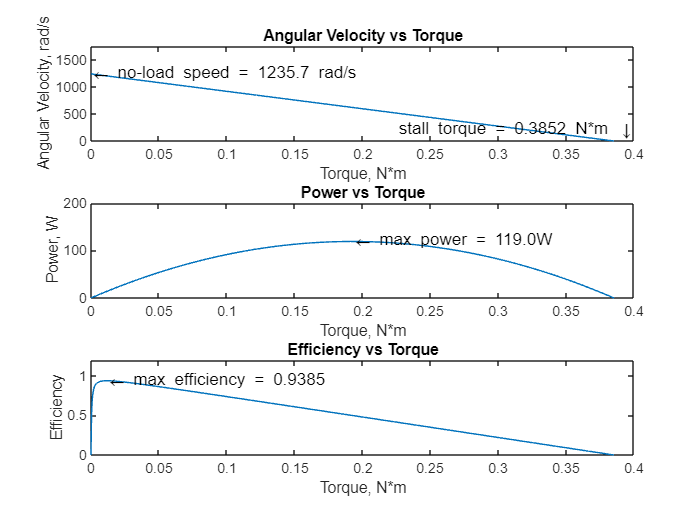

figure(1)
subplot(3,1,1)
plot(T_load, omega_out)
title('Angular Velocity vs Torque')
xlabel('Torque, N*m')
ylabel('Angular Velocity, rad/s')
ylim([0 1750])
text(min(T_load), max(omega_out), '\leftarrow no-load speed = 1235.7 rad/s')
text(max(T_load) - 0.16, min(omega_out)+200, 'stall torque = 0.3852 N*m \downarrow')

subplot(3,1,2)
plot(T_load, P_out)
title('Power vs Torque')
xlabel('Torque, N*m')
ylabel('Power, W')
ylim([0 200])
text(T_load(P_out == max(P_out)), max(P_out), strcat({'\leftarrow '}, sprintf('max power = %.1fW', max(P_out))))

subplot(3,1,3)
plot(T_load, eta_out)
title('Efficiency vs Torque')
xlabel('Torque, N*m')
ylabel('Efficiency')
ylim([0 1.2])
text(T_load(eta_out == max(eta_out)), max(eta_out), strcat({'\leftarrow '}, sprintf('max efficiency = %.4f', max(eta_out))))

2. Plot the no load response of the motor including speed, current, winding temperature, and housing temperature versus time.

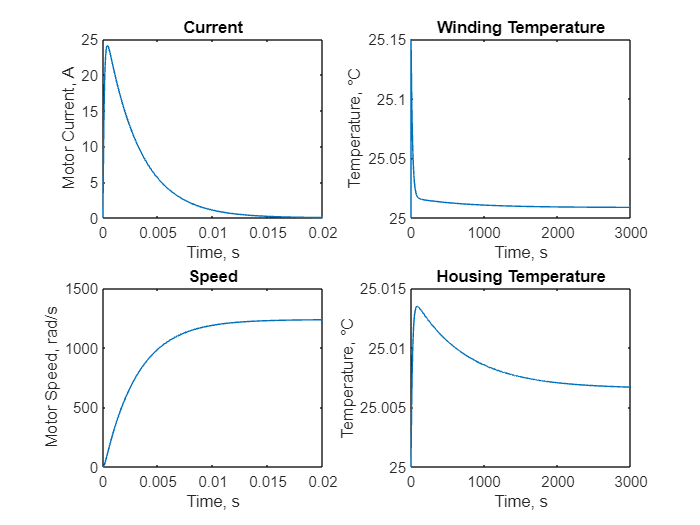

figure(2)
subplot(2,2,1)
plot(no_load_out.tout, no_load_out.i_m)
xlim([0 0.02])
ylim([0 25])
title('Current')
xlabel('Time, s')
ylabel('Motor Current, A')

subplot(2,2,2)
plot(no_load_out.tout, no_load_out.T_wind)
xlim([0 3000])
ylim([25 25.15])
title('Winding Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

subplot(2,2,3)
plot(no_load_out.tout, no_load_out.w_m)
xlim([0 0.02])
ylim([0 1500])
title('Speed')
xlabel('Time, s')
ylabel('Motor Speed, rad/s')

subplot(2,2,4)
plot(no_load_out.tout, no_load_out.T_hous)
xlim([0 3000])
ylim([25 25.015])
title('Housing Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

3. Plot the nominal response of the motor including speed, current, winding temperature, and housing temperature versus time.

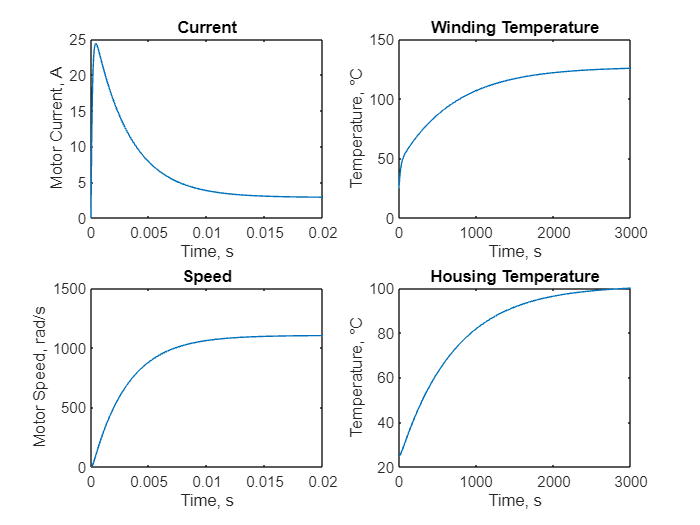

figure(3)
subplot(2,2,1)
plot(nominal_out.tout, nominal_out.i_m)
xlim([0 0.02])
ylim([0 25])
title('Current')
xlabel('Time, s')
ylabel('Motor Current, A')

subplot(2,2,2)
plot(nominal_out.tout, nominal_out.T_wind)
xlim([0 3000])
%ylim([25 30])
title('Winding Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

subplot(2,2,3)
plot(nominal_out.tout, nominal_out.w_m)
xlim([0 0.02])
ylim([0 1500])
title('Speed')
xlabel('Time, s')
ylabel('Motor Speed, rad/s')

subplot(2,2,4)
plot(nominal_out.tout, nominal_out.T_hous)
xlim([0 3000])
%ylim([25 30])
title('Housing Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

4. Plot the stall response of the motor including speed, current, winding temperature, and housing temperature versus time.

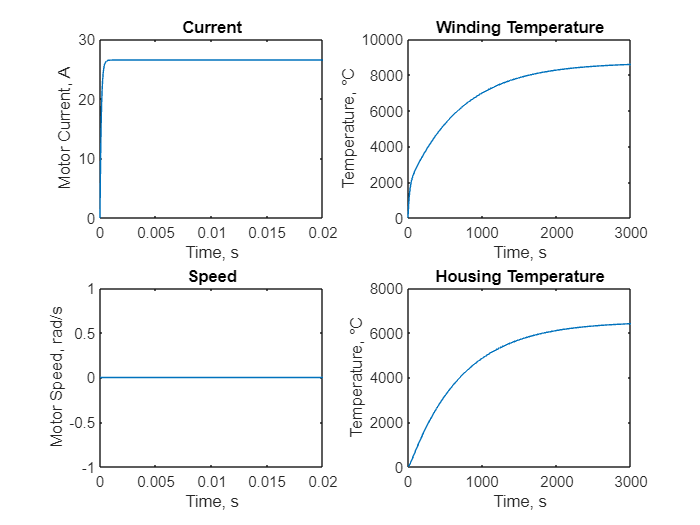

figure(4)
subplot(2,2,1)
plot(stall_out.tout, stall_out.i_m)
xlim([0 0.02])
%ylim([0 25])
title('Current')
xlabel('Time, s')
ylabel('Motor Current, A')

subplot(2,2,2)
plot(stall_out.tout, stall_out.T_wind)
xlim([0 3000])
%ylim([25 30])
title('Winding Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

subplot(2,2,3)
plot(stall_out.tout, stall_out.w_m)
xlim([0 0.02])
%ylim([0 1500])
title('Speed')
xlabel('Time, s')
ylabel('Motor Speed, rad/s')

subplot(2,2,4)
plot(stall_out.tout, stall_out.T_hous)
xlim([0 3000])
%ylim([25 30])
title('Housing Temperature')
xlabel('Time, s')
ylabel('Temperature, °C')

### 4.4.4 Discussion Questions

1. The majority of DC motors are not designed to operate at or near stall conditions due to the buildup of heat in the motor windings. Specifically, what is the main cause of failure for a motor in a stall condition?

The main cause of failure is most likely either the wires, or the insulation preventing the wires in their coils from touching each other, melting due to the extreme heats of motor stalling. If the wires or their insulation melt, the motor can no longer convert electric power to mechanical power, and will have therefore failed. 

2. How can the safe operating current of a motor be increased without modifiying the motor itself?

Improved cooling protocols mean that more heat is lost at any given time, which means that the motor can discharge more energy and still not reach dangerous temperatures. This can be achieved by increasing motor surface area by having a lot of fins or cooling ribs, as well as by having a fan blowing air or a liquid coolant flowing over the motor.

3. How long does it take for the motor to reach 180 [◦C] during a stall condition?

Based on our model, it takes around 2 seconds for the winding to reach 180 degrees, and around 35 seconds for the housing to reach 180 degrees.

4. DC motors are most efficient near their no-load speed. Provide an intuitive explanation why this is the case.

With zero load, there is no ouput power because there is no torque, and at stall torque there is zero power because there is no rotational velocity, meaning both of these cases have zero efficiency. However, power peaks very close to the no-load speed, because with minimal load, there is far less energy lost as heat, and so the output power remains much closer to the input power, which means a higher efficiency. 

5. Even though DC motors should remain at or below their nominal current during steady operation, they can greatly exceed this for short durations. Explain why this is the case.

DC motors should remain at or below their nominal current during steady operation in order to prevent overheating and being damaged. However, they can exceed this for shurt durations because it takes a long time for them to generate the energy needed to be an issue. While the electromechanical system reaches steady state in a fraction of a second, the temperature takes many minutes before it reaches problematic levels. So long as the motor returns to its nominal current quickly enough, it can afford to spend time in the higher areas, because it won't heat up quickly enough to cause problems.

6. The steady-state temperature rise predicted by the thermal model during a stall condition is unrealistic. What unmodeled behavior might limit the temperature rise in a real motor?

The motor would melt or have its power supply interrupted in some way due to the damage it sustains from its elevated temperature. This desctruction would occur well before the motor reaches the temperatures predicted in the stall model, and would limit how hot the motor would be able to get, because once the thermal subsystem can no longer receive energy from the now-destroyed electromechanical subsystem, it will stop heating up.